## Code optimization by vectorizing the loop

producing a one-dimension function array : $f\left(x\right)=A\text{ }sin\left(\frac{x}{2\pi }\right),\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }x=0,1,2,\ldotp \ldotp \ldotp ,\text{ }M−1$

clear;
clc;

for-loop :

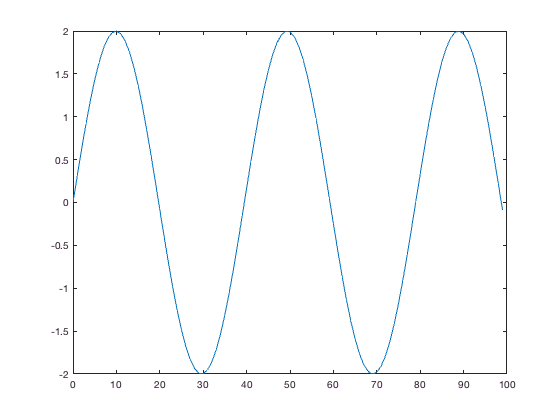

M = 100;    % Assume that M is a constant.
Amplitude = 2.0;

for x = 1:1:M         % Array indices in MATLAB cannot be 0
    f(x) = Amplitude * sin((x-1)/(2*pi));
end
xvector = 0:M-1;
plot(xvector, f)

Vectorizing the loop :

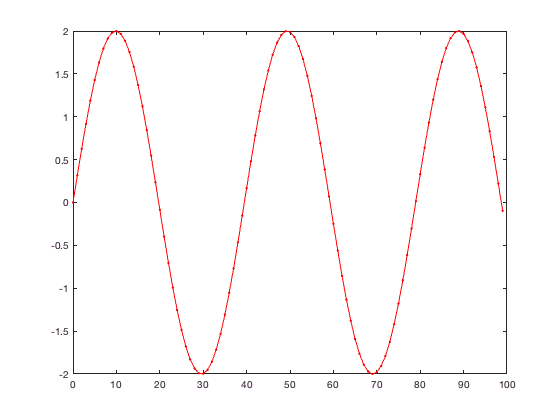

u = 0:M-1;
g = Amplitude * sin(u/(2*pi));
plot(u, g, 'r.-');

## Compare the computation performance between for-loop and vectorization

[time_ratio, image_f, image_g] = twodsin(1, 1/(4*pi), 1/(2*pi), 512, 512);
time_ratio     % Display the time ratio (i.e. the performance) between for-loop and vectorization

time_ratio = 8.1006

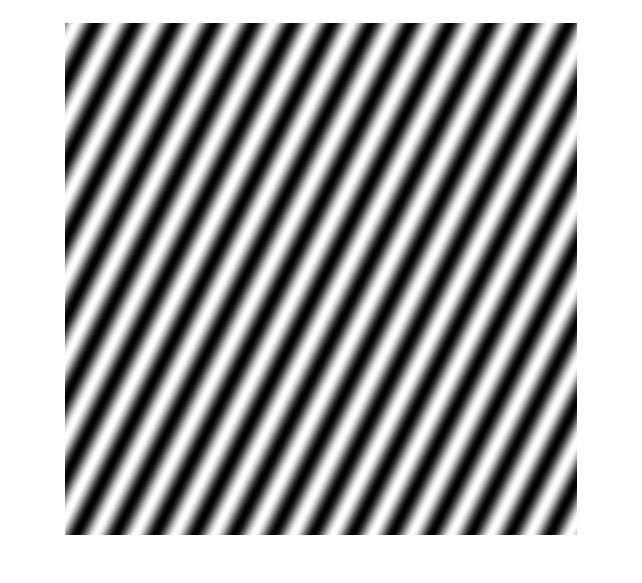


% Generate the image
img = mat2gray(image_g);
imshow(img);